% parameters
m1 = 3.5;
m2 = 1.5;
m3 = 2;
l1 = 1;
l2 = 1.5;
g = 9.8;

a1 = m1 + m2 + m3;
a2 = l1*(m2/2+m3);
a3 = m3*l2/2;
a4 = (m2/3+m3)*l1*l1;
a5 = m3*l1*l2/2;
a6 = m3*l2*l2/3;
g1 = (m2/2+m3)*l1*g;
g2 = m3*l2*g/2;

H = [1; 0; 0];

syms q1 q2 q3 q1d q2d q3d u u_new

M_inv = inv([a1 a2*cos(q2) a3*cos(q3);
             a2*cos(q2) a4 a5*cos(q2-q3);
             a3*cos(q3) a5*cos(q2-q3) a6]);
C = [0 -a2*sin(q2)*q2d -a3*sin(q3)*q3d;
     0 0 a5*sin(q2-q3)*q3d;
     0 -a5*sin(q2-q3)*q2d 0];
G = [0; -g1*sin(q2); -g2*sin(q3)];

A = [zeros([3 3]), eye(3);
     zeros([3 3]), -M_inv*C];
B = [zeros([3 1]);
     M_inv*H];
L = [zeros([3 1]);
     -M_inv*G];

x_dot = simplify(A*[q1;q2;q3;q1d;q2d;q3d] + B*u + L);

Производная вектора состояния исходной нелинейной системы:

collect(x_dot,u)

$$ans = \begin{array}{l} \left(\begin{array}{c} \mathrm{q1d}\\ \mathrm{q2d}\\ \mathrm{q3d}\\ \frac{120\,\cos\left(\sigma_{4}\right)-280}{\sigma_{3}}\,u-\frac{294\,\sin\left(2\,q_{3}\right)-2695\,\sin\left(2\,q_{2}\right)+470\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}\right)+90\,{\mathrm{q3d}}^{2}\,\sin\left(q_{3}\right)+30\,{\mathrm{q2d}}^{2}\,\sigma_{2}+150\,{\mathrm{q3d}}^{2}\,\sigma_{1}}{\sigma_{3}}\\ \left(-\frac{120\,\cos\left(q_{2}-2\,q_{3}\right)-320\,\cos\left(q_{2}\right)}{\sigma_{3}}\right)\,u+\frac{1170\,{\mathrm{q3d}}^{2}\,\sin\left(q_{2}-q_{3}\right)-18718\,\sin\left(q_{2}\right)-4998\,\sigma_{2}+275\,{\mathrm{q2d}}^{2}\,\sin\left(2\,q_{2}\right)+510\,{\mathrm{q2d}}^{2}\,\sin\left(\sigma_{4}\right)+150\,{\mathrm{q3d}}^{2}\,\sin\left(q_{2}+q_{3}\right)}{\sigma_{3}}\\ \left(-\frac{220\,\cos\left(2\,q_{2}-q_{3}\right)-180\,\cos\left(q_{3}\right)}{\sigma_{3}}\right)\,u-\frac{6419\,\sin\left(q_{3}\right)-9163\,\sigma_{1}+1645\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}-q_{3}\right)+30\,{\mathrm{q3d}}^{2}\,\sin\left(2\,q_{3}\right)+510\,{\mathrm{q3d}}^{2}\,\sin\left(\sigma_{4}\right)+55\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}+q_{3}\right)}{\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}-q_{3}\right)\\ \sigma_{2}=\sin\left(q_{2}-2\,q_{3}\right)\\ \sigma_{3}=275\,\cos\left(2\,q_{2}\right)-30\,\cos\left(2\,q_{3}\right)+510\,\cos\left(\sigma_{4}\right)-1385\\ \sigma_{4}=2\,q_{2}-2\,q_{3} \end{array}$$

Для стабилизации двойного перевернутого маятника удобно использовать его линейное представление в нулевой окрестности углов отклонений. Поэтому найдем линеаризацию исходной модели с использованием разложения в ряд Тейлора, а затем и такое управление по обратной связи, при котором поведение исходной модели будет эквивалентно этой линейной структуре (линеаризованной разложением в ряд Тейлора модели).

M_lin_0 = [a1 a2 a3;
           a2 a4 a5;
           a3 a5 a6];
dGdq_lin_0 = [0 0 0;  
              0 -g1 0;
              0 0 -g2];

A_lin_0 = [zeros([3 3]) eye(3);
          -inv(M_lin_0)*dGdq_lin_0 zeros([3 3])];
B_lin_0 = [zeros([3 1]); inv(M_lin_0)*H];

x_dot_lin = simplify(A_lin_0*[q1;q2;q3;q1d;q2d;q3d] + B_lin_0*u_new);

Производная вектора состояния линеаризованной модели:

collect(x_dot_lin)

$$ans = \left(\begin{array}{c} \mathrm{q1d}\\ \mathrm{q2d}\\ \mathrm{q3d}\\ \frac{16\,u_{\mathrm{new}}}{63}+\frac{14\,q_{3}}{15}-\frac{77\,q_{2}}{9}\\ -\frac{20\,u_{\mathrm{new}}}{63}+\frac{1694\,q_{2}}{45}-\frac{238\,q_{3}}{15}\\ \frac{4\,u_{\mathrm{new}}}{63}+\frac{371\,q_{3}}{15}-\frac{1309\,q_{2}}{45} \end{array}\right)$$

Итак, нам необходимо синтезировать такое u = f(x, new_u), чтобы итоговая модель x_dot = ff(x, new_u) имела вид линейной системы.

S4 = solve(x_dot(4) == x_dot_lin(4), u)

$$S4 = \begin{array}{l} \frac{\sigma_{1}\,\left(\frac{14\,q_{3}}{15}-\frac{77\,q_{2}}{9}+\frac{16\,u_{\mathrm{new}}}{63}+\frac{294\,\sin\left(2\,q_{3}\right)-2695\,\sin\left(2\,q_{2}\right)+470\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}\right)+90\,{\mathrm{q3d}}^{2}\,\sin\left(q_{3}\right)+30\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}-2\,q_{3}\right)+150\,{\mathrm{q3d}}^{2}\,\sin\left(2\,q_{2}-q_{3}\right)}{\sigma_{1}}\right)}{120\,\sigma_{2}-280}\\ \mathrm{where}\\ \sigma_{1}=275\,\cos\left(2\,q_{2}\right)-30\,\cos\left(2\,q_{3}\right)+510\,\sigma_{2}-1385\\ \sigma_{2}=\cos\left(2\,q_{2}-2\,q_{3}\right) \end{array}$$

S5 = solve(x_dot(5) == x_dot_lin(5), u)

$$S5 = \begin{array}{l} \frac{\left(\frac{238\,q_{3}}{15}-\frac{1694\,q_{2}}{45}+\frac{20\,u_{\mathrm{new}}}{63}+\frac{1170\,{\mathrm{q3d}}^{2}\,\sin\left(q_{2}-q_{3}\right)-18718\,\sin\left(q_{2}\right)-4998\,\sin\left(q_{2}-2\,q_{3}\right)+275\,{\mathrm{q2d}}^{2}\,\sin\left(2\,q_{2}\right)+510\,{\mathrm{q2d}}^{2}\,\sin\left(\sigma_{2}\right)+150\,{\mathrm{q3d}}^{2}\,\sin\left(q_{2}+q_{3}\right)}{\sigma_{1}}\right)\,\sigma_{1}}{120\,\cos\left(q_{2}-2\,q_{3}\right)-320\,\cos\left(q_{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=275\,\cos\left(2\,q_{2}\right)-30\,\cos\left(2\,q_{3}\right)+510\,\cos\left(\sigma_{2}\right)-1385\\ \sigma_{2}=2\,q_{2}-2\,q_{3} \end{array}$$

S6 = solve(x_dot(6) == x_dot_lin(6), u)

$$S6 = \begin{array}{l} -\frac{\sigma_{1}\,\left(\frac{371\,q_{3}}{15}-\frac{1309\,q_{2}}{45}+\frac{4\,u_{\mathrm{new}}}{63}+\frac{6419\,\sin\left(q_{3}\right)-9163\,\sin\left(2\,q_{2}-q_{3}\right)+1645\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}-q_{3}\right)+30\,{\mathrm{q3d}}^{2}\,\sin\left(2\,q_{3}\right)+510\,{\mathrm{q3d}}^{2}\,\sin\left(\sigma_{2}\right)+55\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}+q_{3}\right)}{\sigma_{1}}\right)}{220\,\cos\left(2\,q_{2}-q_{3}\right)-180\,\cos\left(q_{3}\right)}\\ \mathrm{where}\\ \sigma_{1}=275\,\cos\left(2\,q_{2}\right)-30\,\cos\left(2\,q_{3}\right)+510\,\cos\left(\sigma_{2}\right)-1385\\ \sigma_{2}=2\,q_{2}-2\,q_{3} \end{array}$$

Как видно, выбрать такое u, чтобы линеаризовать все три нелинейные уравнения нельзя. 

Воспользуемся следующим способом линеаризации по всем переменным состояниям, который включает в себя замену переменных.

Докажем, что исходная система является линеаризуемой обратной связью, используя следующую теорему:

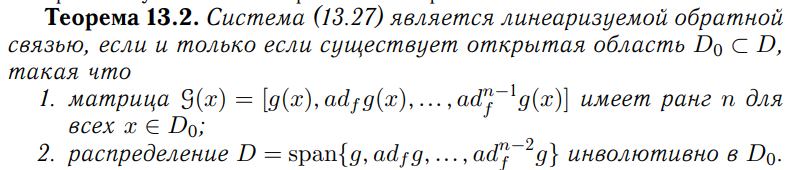

В данной теореме используются понятия скобок Ли и инвариантных распределений. Дадим им определения:

1.

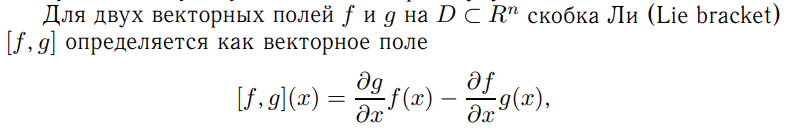

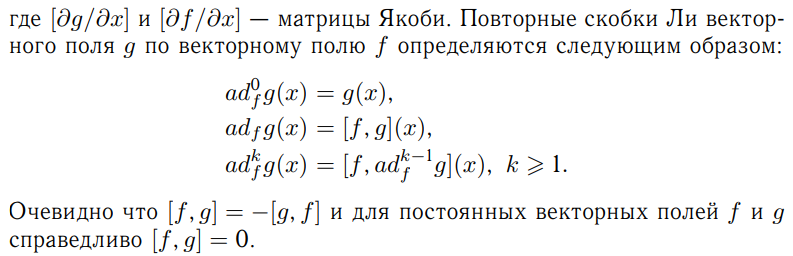

2.

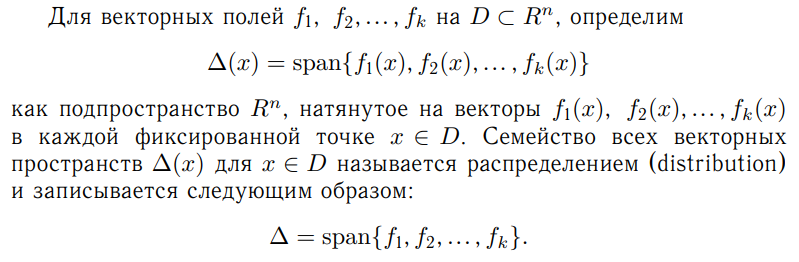

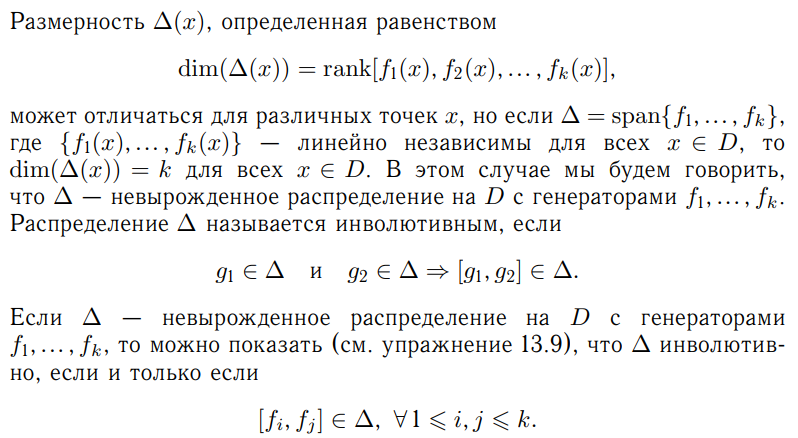

Итак, у нас есть следующая система:

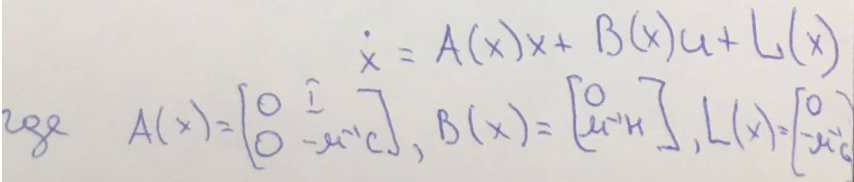

Представим её в виде 

f = simplify(A*[q1;q2;q3;q1d;q2d;q3d] + L)

$$f = \begin{array}{l} \left(\begin{array}{c} \mathrm{q1d}\\ \mathrm{q2d}\\ \mathrm{q3d}\\ -\frac{294\,\sin\left(2\,q_{3}\right)-2695\,\sin\left(2\,q_{2}\right)+470\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}\right)+90\,{\mathrm{q3d}}^{2}\,\sin\left(q_{3}\right)+30\,{\mathrm{q2d}}^{2}\,\sigma_{2}+150\,{\mathrm{q3d}}^{2}\,\sigma_{1}}{\sigma_{3}}\\ \frac{1170\,{\mathrm{q3d}}^{2}\,\sin\left(q_{2}-q_{3}\right)-18718\,\sin\left(q_{2}\right)-4998\,\sigma_{2}+275\,{\mathrm{q2d}}^{2}\,\sin\left(2\,q_{2}\right)+510\,{\mathrm{q2d}}^{2}\,\sin\left(\sigma_{4}\right)+150\,{\mathrm{q3d}}^{2}\,\sin\left(q_{2}+q_{3}\right)}{\sigma_{3}}\\ -\frac{6419\,\sin\left(q_{3}\right)-9163\,\sigma_{1}+1645\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}-q_{3}\right)+30\,{\mathrm{q3d}}^{2}\,\sin\left(2\,q_{3}\right)+510\,{\mathrm{q3d}}^{2}\,\sin\left(\sigma_{4}\right)+55\,{\mathrm{q2d}}^{2}\,\sin\left(q_{2}+q_{3}\right)}{\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}-q_{3}\right)\\ \sigma_{2}=\sin\left(q_{2}-2\,q_{3}\right)\\ \sigma_{3}=275\,\cos\left(2\,q_{2}\right)-30\,\cos\left(2\,q_{3}\right)+510\,\cos\left(\sigma_{4}\right)-1385\\ \sigma_{4}=2\,q_{2}-2\,q_{3} \end{array}$$

g = simplify(B)

$$g = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{8\,\left(3\,\cos\left(2\,q_{2}-2\,q_{3}\right)-7\right)}{\sigma_{1}}\\ -\frac{24\,\cos\left(q_{2}-2\,q_{3}\right)-64\,\cos\left(q_{2}\right)}{\sigma_{1}}\\ -\frac{4\,\left(11\,\cos\left(2\,q_{2}-q_{3}\right)-9\,\cos\left(q_{3}\right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=55\,\cos\left(2\,q_{2}\right)-6\,\cos\left(2\,q_{3}\right)+102\,\cos\left(2\,q_{2}-2\,q_{3}\right)-277 \end{array}$$

Размерность системы равна 6. Найдем матрицу S(x) и вычислим её ранг

ad_fg = simplify(jacobian(g,[q1;q2;q3;q1d;q2d;q3d])*f - jacobian(f,[q1;q2;q3;q1d;q2d;q3d])*g)

ad2_fg = simplify(jacobian(ad_fg,[q1;q2;q3;q1d;q2d;q3d])*f - jacobian(f,[q1;q2;q3;q1d;q2d;q3d])*ad_fg)

К сожалению, из-за высокой сложности вычислений, проверить систему на линеаризуемость обратной связью и, в успешном случае найти такой диффеоморфизм z=T(x), который преобразует координаты таким образом, что можно выбрать управление u, такое что нелинейная система сможет быть записана в виде эквивалентной линейной не удастся.